# Code JavaScript Response to Data Change in MATLAB

Create an `htmlComponent` JavaScript® object that displays the data that is set on an HTML UI component in MATLAB®.

First, create an empty HTML UI component and position it within a figure.

fig = uifigure;
fig.Position = [500 500 490 180];

h = uihtml(fig);
h.Position = [20 20 450 130];

Then, create an HTML file called `displayDataFromMATLAB.html`. In the file, 

- Use a `style` tag to define internal CSS styles for the `<div>` elements that display text.

- Write a `setup` function inside of a `<script>` tag to connect your JavaScript object, called `htmlComponent`, to the HTML UI component you created in MATLAB.

- Add an event listener within the `setup` function. The event listener listens for `"DataChanged"` events on the `htmlComponent` JavaScript object and creates a listener callback function. When a `"DataChanged"` event occurs, the listener callback function updates the `"dataDisplay"` `<div> element` with the value that is set to the `Data` property in MATLAB.

Now, in MATLAB, set the value of the `HTMLSource` property to the path to the HTML file.

h.HTMLSource = fullfile('E:\semester 4\intro to ai robotics\project\Final\SimulationPage.html');

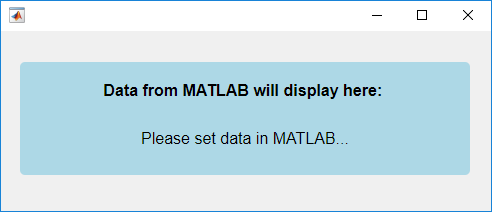

Set the value of the `Data` property for the HTML UI component.  Notice how the `htmlComponent` JavaScript object updates in your HTML UI component.

h.Data = "Hello World!";

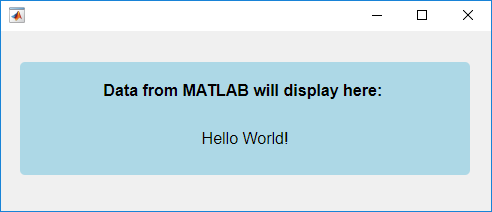

*Copyright 2019 The MathWorks, Inc.*